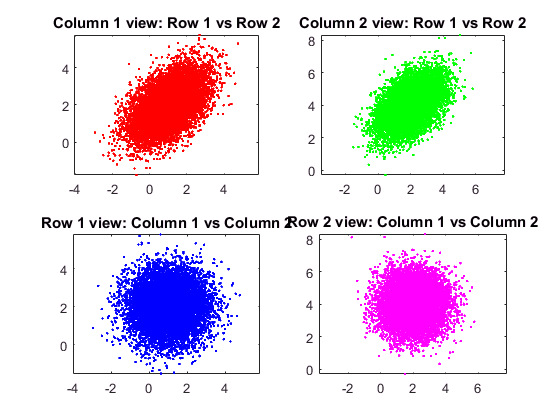

% matrix Gaussian distribution
clc
clear 
close all


seed=128; % set a random seed
rng(seed);
N = 10000; % the number of points

mu1 = [1;2]; 
sigma1 = [1 0;0 1];  
mu2 = [2;4];
sigma2 = [1 0.5;0.5 1];

Mu = [mu1;mu2]; % produce a mean matrix using reshaping directly
Sigma = kron(sigma1,sigma2); % produce a new covariance matrix using kronecker product

sample = mvnrnd(Mu,Sigma,N); % generate a multivariate Gaussian distribition sample using 
                             % the previous mean matrix and covariance matrix
sample = reshape(sample',2,2,N); % convert vector to matrix

% plot the matrix from columan and row veiw
subplot(2,2,1)
col1_view_row1 = reshape(sample(1,1,:),N,1);
col1_view_row2 = reshape(sample(2,1,:),N,1);
plot(col1_view_row1,col1_view_row2,'r.')
axis equal
title('Column 1 view: Row 1 vs Row 2')

subplot(2,2,2)
col2_view_row1 = reshape(sample(1,2,:),N,1);
col2_view_row2 = reshape(sample(2,2,:),N,1);
plot(col2_view_row1,col2_view_row2,'g.')
axis equal
title('Column 2 view: Row 1 vs Row 2')

subplot(2,2,3)
row1_view_col1 = reshape(sample(1,1,:),N,1);
row1_view_col2 = reshape(sample(1,2,:),N,1);
plot(row1_view_col1,row1_view_col2,'b.')
title('Row 1 view: Column 1 vs Column 2')
axis equal

subplot(2,2,4)
row2_view_col1 = reshape(sample(2,1,:),N,1);
row2_view_col2 = reshape(sample(2,2,:),N,1);
plot(row2_view_col1,row2_view_col2,'m.')
axis equal
title('Row 2 view: Column 1 vs Column 2')